# Hexapod - Simple

Traverse smooth, known maze.

## Create maze

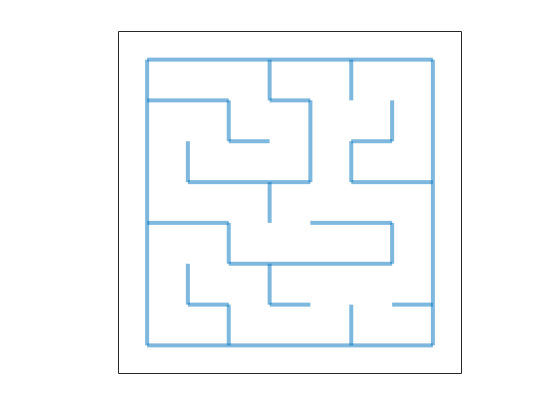

branching = 8;
mazeCreator(branching,'middle',false,false);
pad = 24;
maze = getframe(gca).cdata(pad:end-pad,pad:end-pad,1);

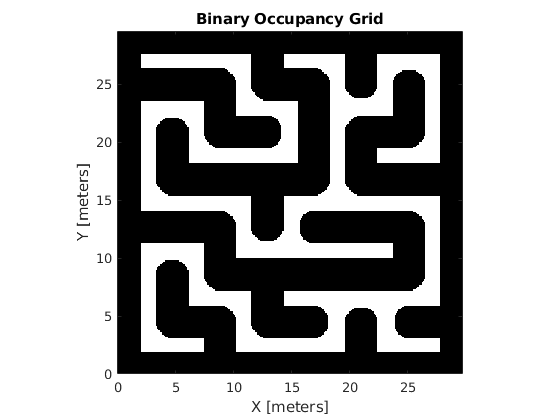

%turn maze into occupancy grid
maze = imbinarize(maze);
maze = imcomplement(maze);
res = 10;
map = binaryOccupancyMap(maze, res);

robotBoundingRadius = 1.2;
map.inflate(robotBoundingRadius);
figure;
show(map)

## Setup state space and planner

%SE(2) state space - rotation not relevant
ss = stateSpaceSE2;
ss.StateBounds = [map.XLocalLimits; map.YLocalLimits; -pi pi];
validator = validatorOccupancyMap(ss);
validator.Map = map;

%RRT* planner
planner = plannerRRTStar(ss,validator);
planner.MaxIterations=1e6;
planner.MaxNumTreeNodes=1e6;
planner.MaxConnectionDistance = 1;

 

## Plan path

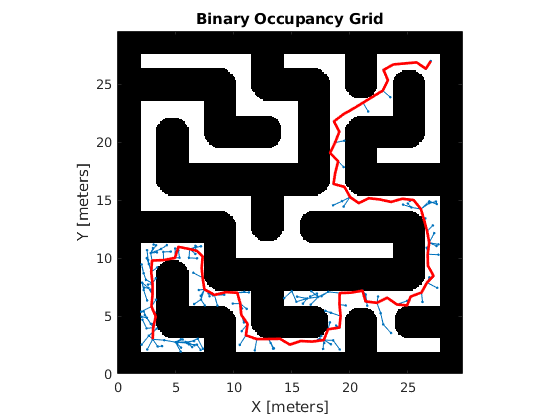

startPose = [3 3 0]; 
goalPose = [27 27 0];

[refpath, solnInfo] = plan(planner, startPose, goalPose);
map.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(refpath.States(:,1),refpath.States(:,2),'r-','LineWidth',2); % draw path


waypoints = refpath.States(:,1:2);

 

## Run simulation

Ts = 0.1;
Tf = 130;
open_system('simple');
simout = sim('simple', [0 Tf]);

 

## Compare planned vs executed trajectory

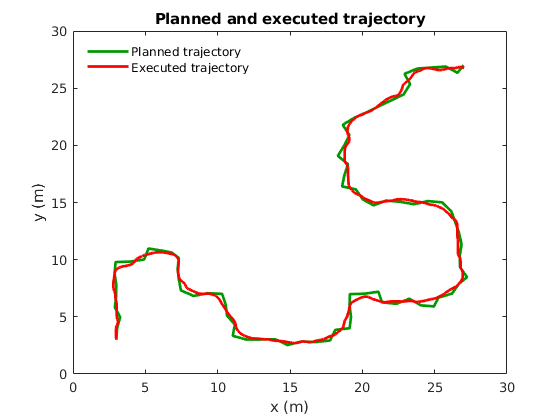

state = simout.yout{1}.Values.Data;
figure;
hold on
plot(refpath.States(:,1),refpath.States(:,2),'-','LineWidth',2, 'Color', [0 0.6 0]); % draw path
plot(state(:,1), state(:,2), '-', 'LineWidth', 2, 'Color', 'red')
box on
legend('Planned trajectory', 'Executed trajectory');
legend box off
xlabel 'x (m)'
ylabel 'y (m)'
legend location northwest
title('Planned and executed trajectory');

## Visualise state estimation

time = linspace(0, Tf, length(simout.yout{1}.Values))

time = 130

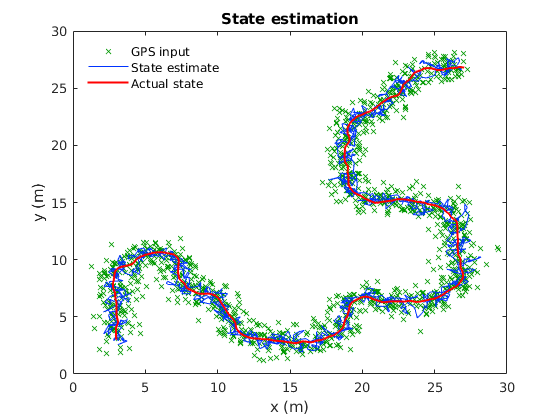

state = simout.yout{1}.Values.Data;
state_KF = simout.yout{2}.Values.Data;
state_GPS = simout.yout{3}.Values.Data;

figure;
hold on
plot(state_GPS(:,1), state_GPS(:,2), 'x','markersize', 4, 'Color', [0 0.6 0])
plot(state_KF(:,1), state_KF(:,2), '-', 'Color', [0 0.2 1]);
plot(state(:,1), state(:,2), '-', 'LineWidth', 1.5, 'Color', 'red')
box on
legend('GPS input', 'State estimate', 'Actual state')
legend box off
xlabel 'x (m)'
ylabel 'y (m)'
legend location northwest
title('State estimation');